clear; %Limpio Espacio de trabajo
clc;

narm=500; %Numero de armonicos tomados para reconstruir la señal

A=1; %Amplitud rampa

Tr=1; %Periodo rampa
To=10; %Periodo ceros
T=Tr+To; %Periodo de la señal

f=1/T; %Frecuencia
fs=(1/T):1/T:(narm/T); %Normalizacion vector de Frecuencia

np=T*0.01; %Espacio numerico definido en el periodo de la funcion (np=Numero de muestras en un periodo)
t=-(2*T):np:(2*T); %Limites del espacio numerico (eje de abscisas ¨tiempo¨)

%dds = tripuls(t,0.2,-1); %Funcion de referencia ¨Diente de sierra original¨
tpul = 0;%pulstran(t,d,x,f);

%---------------------------CALCULO DE COEFICIENTES--------------------------
%---------------------------Bn--------------------------
syms x n;
dib=(x/Tr)*sin(2*pi*n*f*x); %Expresion dentro de la integral b 'dib'
bn=(2/T)*int(dib,[0 Tr]); %Integral definida en el periodo de la rampa
bn=simplify(bn)

$$bn = \frac{11\,\sin\left(\frac{2\,\pi \,n}{11}\right)-2\,\pi \,n\,\cos\left(\frac{2\,\pi \,n}{11}\right)}{2\,n^{2}\,\pi^{2}}$$

%---------------------------An--------------------------
syms x n;
dia=(x/Tr)*cos(2*pi*n*f*x); %Expresion dentro de la integral a 'dia'
an=(2/T)*int(dia,[0 Tr]);
an=simplify(an)

$$an = -\frac{11\,{\sin\left(\frac{\pi \,n}{11}\right)}^{2}-\pi \,n\,\sin\left(\frac{2\,\pi \,n}{11}\right)}{n^{2}\,\pi^{2}}$$

%---------------------------Ao--------------------------
syms x n;
diao=(x/Tr); %Expresion dentro de la integral a 'diao'
ao=(2/T)*int(diao,[0 Tr])

$$ao = \frac{1}{11}$$

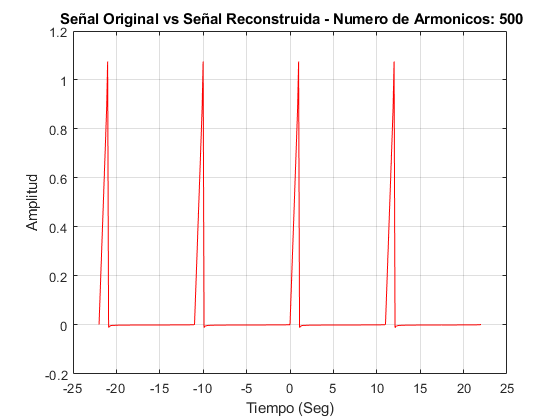

ao=double(ao);
%-----------------------------------------------------------------------------

%--------------------Ciclo sumatoria coeficientes---------------------------
Sefu=ao/2;% Inicializo con el nivel DC
for n=1:narm %Ciclo de sumatoria (desde n=1 hasta el numero de armonicos deseados (narm))
anf=subs(an);%Evaluo el coeficiente a en n
anf=double(anf);%Convierto el coeficiente en numero para optimizar calculos
Sefua=anf*cos(2*pi*n*f*t);
bnf=subs(bn);
bnf=double(bnf);
Sefub=bnf*sin(2*pi*n*f*t);
mag(n)=sqrt(bnf^2+anf^2);%Vector del espectro de magnitud
Sefu=Sefu+(Sefua+Sefub);
end
%-----------------------------------------------------------------------------


%--------------------Graficacion de Resultados---------------------------
plot(t,tpul,'b',t,Sefu,'r'),grid on,xlabel 'Tiempo (Seg)', ylabel Amplitud; %Graficacion de Resultados
title(['\bf Señal Original vs Señal Reconstruida - Numero de Armonicos: ',num2str(n),'']);

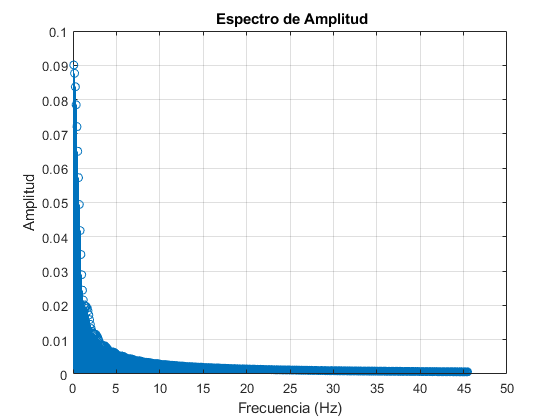

stem(fs,mag),grid on,xlabel 'Frecuencia (Hz)', ylabel Amplitud; %Graficacion de Resultados
title('\bf Espectro de Amplitud');

%-----------------------------------------------------------------------------